# Prelab Masse og kraft, spørsmål 9

I filen Vbro.mat ligger et signal som vi kan tenke oss er tatt opp med skriptet 'les\_2osc'. Last Vbro.mat inn i matlab og plot signalet   e. Her er noen ting dere må legge inn i skriptet dere skriver:

- sampleraten er 1000 Hz;

- amplituden til den påtrykte spenningen   E er 5 V;

- frekvensen til den påtrykte spenningen   E er 10 Hz.

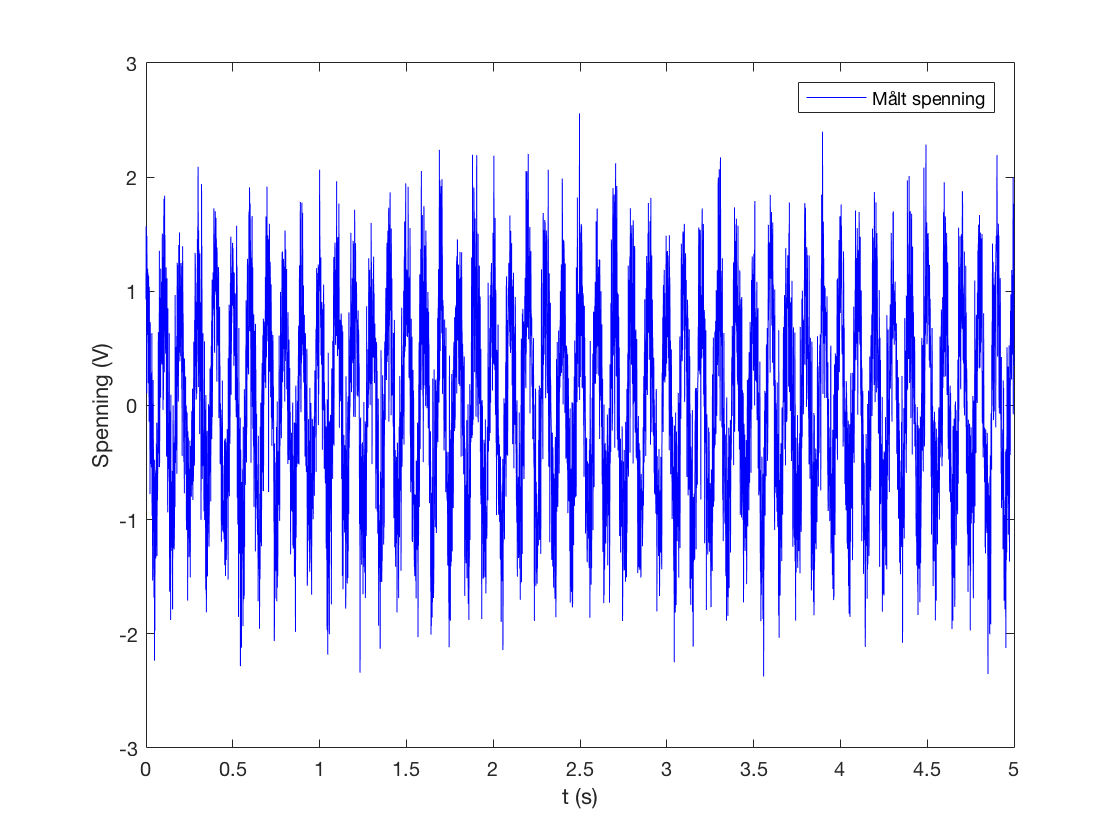

load Vbro.mat % Read in sampled voltage e
              % In this script e is called Vbro until we filter it.
A = 5; % Amplitude of voltage sinus input to bridge
setfreq = 10; % frequency of signal over bridge (Hz) 
sampleR = 1000; % Sample rate in Hz Vbro is measured at

% NB!! Must use even number of samples for FFT unless we use "symmetric" option!!
nsamples = floor(length(Vbro)/2)*2;
% Truncates Vbro by 1 if number of samples is odd
Vbro = Vbro(1:nsamples);

% time axis starting at 0
t = (0:length(Vbro)-1)/sampleR; 

% Frequency axis with as many points
% as voltage measurements
f = sampleR*linspace(0,1-1/length(Vbro),length(Vbro)); 

% Plot the raw sampled voltage versus time
figure(2), hold off
plot(t,Vbro,'b');
legend('Målt spenning')
xlabel('t (s)')
ylabel('Spenning (V)')
hold on

Skript skal beregne forholdet mellom effektivverdien av  e og  E (se figuren), og som dermed er et mål på ubalansen i  broen (og bør være proporsjonalt med utslaget til fjæra). For å gjøre  dette bruker dere **fft**-algoritmen i matlab for å finne frekvensspekteret til det målte signalet.

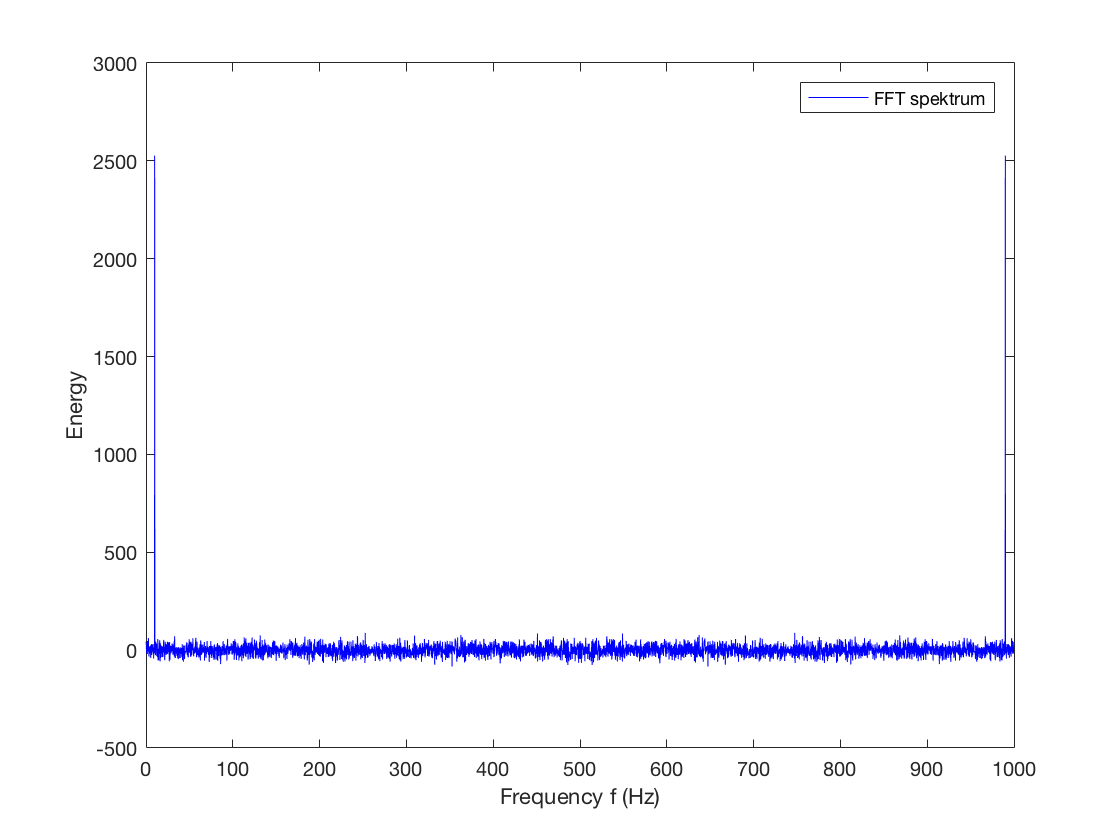

Y = fft(Vbro); % Fourier transform

figure(1)
plot(f,real(Y),'b');
xlabel('Frequency f (Hz)')
ylabel('Energy')
legend('FFT spektrum')
hold on

% Find the index of the frequency with maximum absolute amplitude
% and extract the frequency there. Compare it to the set frequency.
% They should be approximately equal!

[sortedvalues,sortedindices] = sort(abs(Y(1:floor(length(Y)/2))),'descend');
maxfreq = f(sortedindices(1));
fprintf('Frequencies set and found: %.1f Hz, %.1f Hz\n',setfreq,maxfreq)

Frequencies set and found: 10.0 Hz, 10.0 Hz


Dere skal så fjerne alle frekvenser som ikke ligger i nærheten av  frekvensen på det påtrykte signalet. Dette kan gjøres ved å gange med en filtreringsfunksjon, og da brukes gjerne en Gauss-kurve. Bruk et  standardavvik på 5% av påtrykt frekvens.

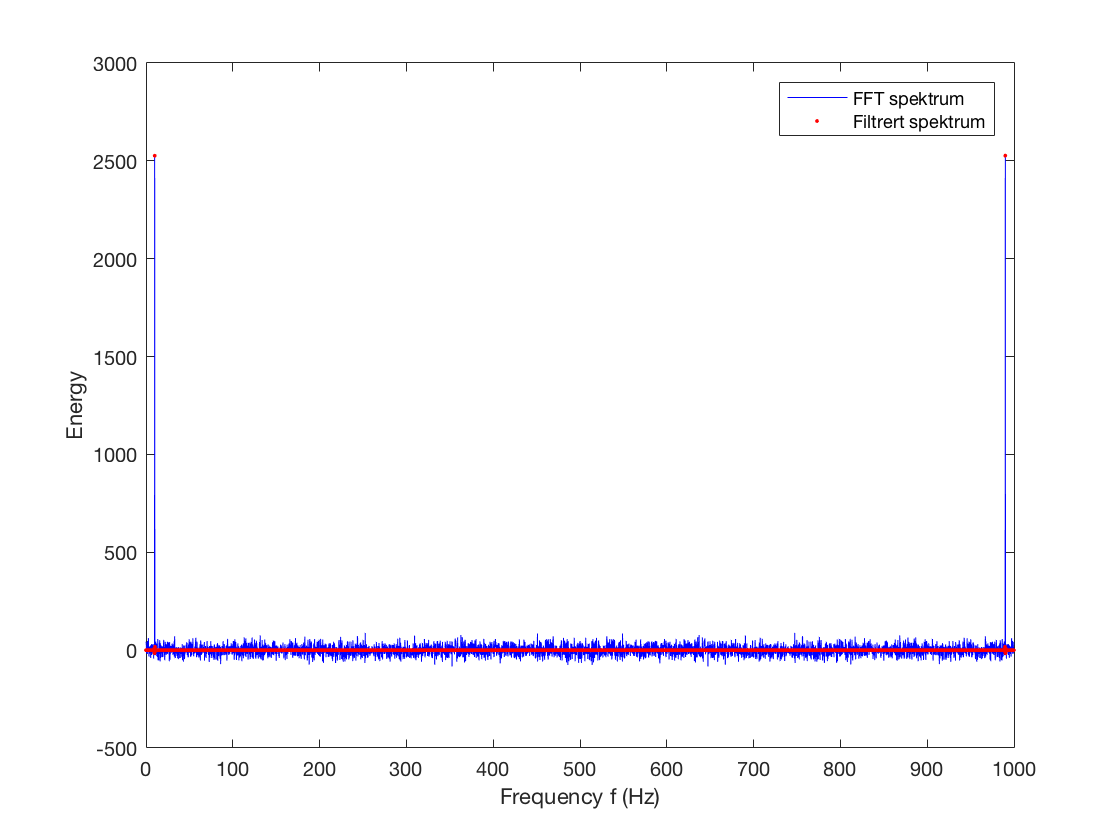

% Remember to filter both the peak at maxfreq
% and the second one at the end of the doubled 
% frequency spectrum.

sigma = 0.05*maxfreq;
filter = exp(-(f-maxfreq).^2./(2*sigma^2)) + exp(-(f-(sampleR-maxfreq)).^2./(2*sigma^2)) ;

y = Y.*filter;
figure(1), hold on
plot(f,real(y),'r.','MarkerSize',4)

legend('FFT spektrum','Filtrert spektrum')

Konverter deretter signalet tilbake til et vanlig tidvarierende signal med **ifft**, og finn effektivverdien av signalet (det kan være nødvendig å tvinge  matlab til å behandle frekvenspekteret som symmetrisk ved  tilbaketransformering for å få et reelt signal tilbake).

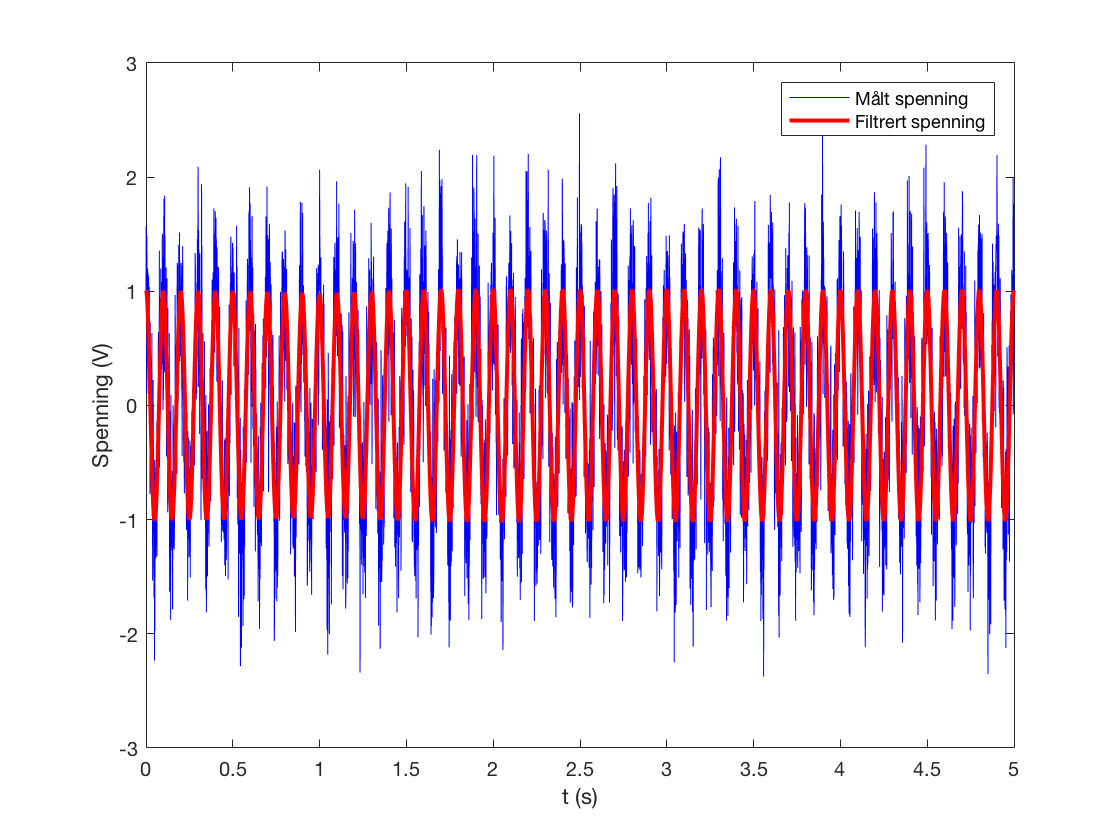

% Plot the input and frequency-filtered voltage versus time
figure(2)

% Perform the inverse fast fourier transform on the filtered
% frequency spectrum y to extract the signal with the specified
% frequency.
e = ifft(y);

%plot(t,Vbro);

plot(t,real(e),'r','LineWidth',2);
legend('Målt spenning','Filtrert spenning')


% Calculate the ratio of the rms of the filtered signal to the
% voltage input to the bridge (A=5 V sinus, so rms(E)=A/sqrt(2)).

ratio = rms(real(e))/(A/sqrt(2));
fprintf('Ratio of RMS of filtered output signal e\nto RMS of input signal E: %.3f\n',ratio)

Ratio of RMS of filtered output signal e
to RMS of input signal E: 0.202
